***1 a)***

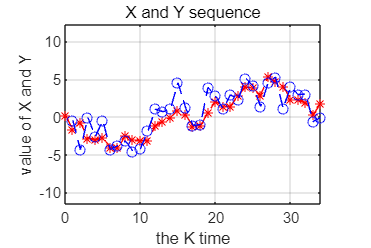

%set the parameters 
x_0=2;
P_0=8;
Q=1.5;
R=3;
A=1;
H=1;
N=34;
%use functions to get sequences
X_s=genLinearStateSequence(x_0, P_0, A, Q, N);
Y_s=genLinearMeasurementSequence(X_s,H,R);

figure('Position',[300 300 600 400]);
h1 = plot(0:34,X_s,'r--*');
hold on
axis equal
h2 = plot(1:34,Y_s,'b--o');
hold off
grid on 
xlabel('the K time') % Set x-axis label
ylabel('value of X and Y') % Set y-axis label
title('X and Y sequence')

***1 b)***

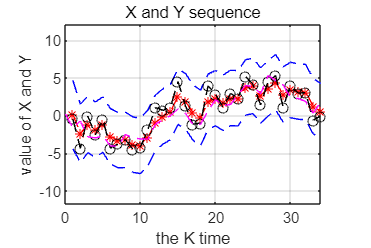

% Use the KalmanFilter to get X,P estimate
[X_est, P_e,~,~,~] = kalmanFilter(Y_s,x_0, P_0, A, Q, H, R);

%change the sigma^2 P_e into a two dimension array so we cancalculate later
P_est =[];
for i =1:length(X_est)
    P_est =[P_est P_e(:,:,i)];
end
%P_est=reshape(P_e,1,34);
%get 3 sigma level
Sigma3  = X_est+3*sqrt(P_est);
Sigma_3 = X_est-3*sqrt(P_est); 

figure('Position',[300 300 600 400]);
plot(1:34,X_est,'r--*');
hold on
axis equal
plot(1:34,Sigma3,'b--');
hold on
plot(1:34,Sigma_3,'b--');
hold on
plot(1:34, Y_s, 'k--o');
hold on
plot(0:34, X_s, 'm--');
hold off
grid on 
xlabel('the K time')
ylabel('value of X and Y')  
title('X and Y sequence')

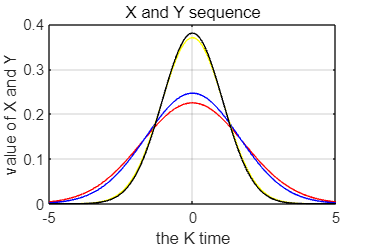

figure('Position',[300 300 600 400]);
[X1,Y1] =getnormpdf(0,abs(X_s(:,2)-X_est(:,1)),5,0.1);
plot(X1,Y1,'r');
hold on
[X2,Y2] =getnormpdf(0,abs(X_s(:,3)-X_est(:,2)),5,0.1);
plot(X2,Y2,'b');
hold on
[X4,Y4] =getnormpdf(0,abs(X_s(:,5)-X_est(:,4)),5,0.1);
plot(X4,Y4,'y');
hold on
[X30,Y30] =getnormpdf(0,abs(X_s(:,31)-X_est(:,30)),5,0.1);
plot(X30,Y30,'k');
hold off
grid on 
xlabel('the K time')
ylabel('value of X and Y')  
title('X and Y sequence')

***1 c)***

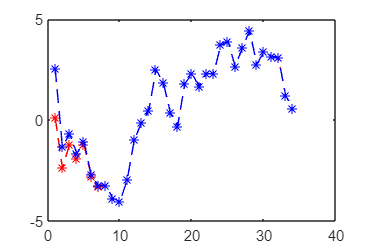


% Use the KalmanFilter to get X,P estimate
[X_est, P_est,~,~,~] = kalmanFilter(Y_s,x_0, P_0, A, Q, H, R);

% Use the KalmanFilter to get X,P estimate
[X_ew, P_ew,~,~,~] = kalmanFilter(Y_s, 12 , P_0, A, Q, H, R);

figure('Position',[300 300 600 400]);
plot(1:34,X_est,'r--*');
hold on
plot(1:34,X_ew,'b--*');
hold off

1 d)

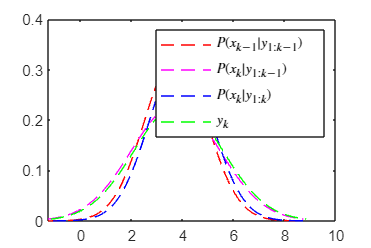

[X_up, P_u,X_pre,P_pr,~] = kalmanFilter(Y_s,x_0, P_0, A, Q, H, R);

P_up =[];
for i =1:length(X_up)
    P_up =[P_up P_u(:,:,i)];
end
P_pre =[];
for i =1:length(X_up)
    P_pre =[P_pre P_pr(:,:,i)];
end


figure('Position',[300 300 600 400]);
n=25;
%n=<34
[X_mu,Y_mu] =getnormpdf(X_up(:,n-1),sqrt(P_up(:,n-1)),5,0.1);
[X_np,Y_np] =getnormpdf(X_pre(:,n),sqrt(P_pre(:,n)),5,0.1);
[X_nu,Y_nu] =getnormpdf(X_up(:,n),sqrt(P_up(:,n)),5,0.1);
[X_y,Y_y] =getnormpdf(H*X_s(:,n+1),sqrt(R),5,0.1);
% [X_y,Y_y] =getnormpdf(Y_s(:,n),sqrt(R),5,0.1);
plot(X_mu,Y_mu,'r--');
hold on
plot(X_np,Y_np,'m--');
hold on
plot(X_nu,Y_nu,'b--');
hold on
plot(X_y,Y_y,'g--');
legend('$P(x_{k-1}|y_{1:k-1})$','$P(x_{k}|y_{1:k-1})$','$P(x_{k}|y_{1:k})$','$y_k$','interpreter','latex')
hold off

***1 e)***

1)

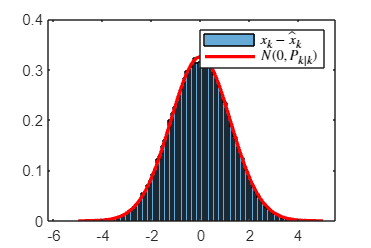

N_l=100000;
X_l=genLinearStateSequence(x_0, P_0, A, Q, N_l);
Y_l=genLinearMeasurementSequence(X_l,H,R);
[X_estl, P_el,~,~,~] = kalmanFilter(Y_l,x_0, P_0, A, Q, H, R);
%reshape the P_el to 1 dimension
P_estl =[];
for i =1:length(X_estl)
    P_estl =[P_estl P_el(:,:,i)];
end
% get x_k-x_estimate
X_delta=X_l(:,2:end)-X_estl;
%get the distribution N(0,P_{k|k})
[X_d,Y_d] =getnormpdf(0,sqrt(P_estl(N_l)),5,0.1);

figure('Position',[300 300 600 400]);
histogram(X_delta,'Normalization','pdf');
hold on
plot(X_d,Y_d,'r','Linewidth',2);
hold off
legend('$x_k-\hat x_k$','$N(0,P_{k|k})$','interpreter','latex')

2)

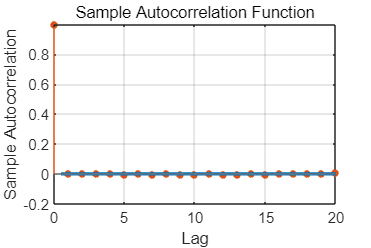

[~, ~,~,~,V] = kalmanFilter(Y_l,x_0, P_0, A, Q, H, R);
autocorr(V)

***2 a)***

load SensorMeasurements.mat
[mu_10, Sigma_10] = get_mean_cov(CalibrationSequenceVelocity_v10);
[mu_20, Sigma_20] = get_mean_cov(CalibrationSequenceVelocity_v20);
Cali=[CalibrationSequenceVelocity_v0,CalibrationSequenceVelocity_v10-mu_10,CalibrationSequenceVelocity_v20-mu_20];
[~, Sigma] = get_mean_cov(Cali);
C=mu_20/20;
R=Sigma/(C^2);

***2 b)***

Y_pvo=Generate_y_seq();


% The we we deal with NAN data, this is already included in the Kalmen
% filter

% Y_pv=[];
% for i=1:2000
%    if ~isnan(Y_pvo(:,i)) 
%      Y_pv=[Y_pv,Y_pvo(:,i)];
%    end
% end

2 c)

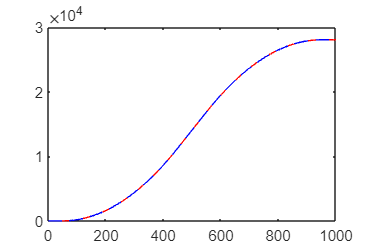

T=0.2;

% constant velocity model
x_pv=[0;0];
P_pv=[0,0;0,0];
A=[1,T;0,1];
H=[1,0;0,C];
Q=[10,0;0,10];
R=[1,0;0,Sigma];

[X_cv,P_cv,~,~,~] = kalmanFilter(Y_pvo,x_pv, P_pv, A, Q, H, R);

% constant acceleration model

x_a=[0;0;0];
P_a=[0,0,0;0,0,0;0,0,0];

A_a=[1,T,T^2/2;0,1,T;0,0,1];
H_a=[1,0,0;0,C,0];
Q_a=[100,0,0;0,100,0;0,0,100];
R_a=[1,0;0,Sigma];

[X_ca,P_ca,~,~,~] = kalmanFilter(Y_pvo,x_a, P_a, A_a, Q_a, H_a, R_a);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%GET TRUE x SEQUENCE

X = genLinearStateSequence(x_a, P_a, A_a, Q_a, 1000);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure('Position',[300 300 600 400]);
plot(1:length(X_cv),X_cv(1,:),'r');
hold on
% plot(1:length(X),X(1,:),'y');
% hold on
plot(1:length(X_ca),X_ca(1,:),'b--');
hold off

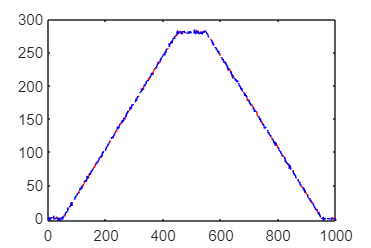



figure('Position',[300 300 600 400]);
plot(1:length(X_cv),X_cv(2,:),'r--');
hold on
% plot(1:length(X),X(2,:),'y');
% hold on
plot(1:length(X_ca),X_ca(2,:),'b--');
hold off

***The functions that might be used in the tasks***

function [X,Y] =getnormpdf(mu,sigma,a,b)
%this function get the Gaussian distribution figure
% mu and sigma define distribution
% a defines the sampling range, b defines the sampling interval
X=(mu-a):b:(mu+a);
Y=normpdf(X,mu,sigma);

end

function [mu, Sigma] = get_mean_cov(Y)
%this function get the mean and cov of Y
mu=mean(Y,2);
Sigma = zeros(length(mu),length(mu));
for i = 1:length(Y)
    sigma = (Y(:,i)-mu)*(Y(:,i)-mu)';
    Sigma = Sigma+sigma;
end    
Sigma= Sigma/(length(Y)-1);
end

function X = genLinearStateSequence(x_0, P_0, A, Q, N)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
mu=(mvnrnd(x_0,P_0))';

X=[mu];
for i= 1:N
    mu=A*mu+(mvnrnd(zeros(length(Q),1),Q))';
    X=[X mu];
    
end
end


function Y = genLinearMeasurementSequence(X, H, R)
%GENLINEARMEASUREMENTSEQUENCE generates a sequence of observations of the state 
% sequence X using a linear measurement model. Measurement noise is assumed to be 
% zero mean and Gaussian.
%
%Input:
%   X           [n x N+1] State vector sequence. The k:th state vector is X(:,k+1)
%   H           [m x n] Measurement matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% your code here
Y=[];
for i=2:length(X)
    y=H*X(:,i)+(mvnrnd(zeros(length(R),1),R))';
    Y=[Y y];
end
end

function [X, P,X_p, P_p,V] = kalmanFilter(Y_data, x_0, P_0, A, Q, H, R)
%KALMANFILTER Filters measurements sequence Y using a Kalm0an filter. 
%
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x N] Estimated state vector sequence
%   P           [n x n x N] Filter error convariance
%
%% process Y_data

Y=[];
for i=1:length(Y_data)
   if ~isnan(Y_data(:,i)) 
     Y=[Y,Y_data(:,i)];
   end
end

%% Parameters
N = size(Y,2);

n = length(x_0);
m = size(Y,1);

%% Data allocation
X = zeros(n,N);
P = zeros(n,n,N);
V = zeros(m,N);


X_p = zeros(n,N);
P_p = zeros(n,n,N);

x_up=x_0;
P_up=P_0;

for i=1:N
[x_pre, P_pre] = linearPrediction(x_up, P_up, A, Q);
[x_up, P_up, v_up] = linearUpdate(x_pre, P_pre, Y(:,i), H, R);


X_p(:,i)=x_pre;
P_p(:,:,i)=P_pre;

X(:,i)=x_up;
V(:,i)=v_up;
P(:,:,i)=P_up;
end

end


function [x, P] = linearPrediction(x, P, A, Q)
x=A*x;
P=A*P*A'+Q;
end
function [x, P, v] = linearUpdate(x, P, y, H, R)
v=y-H*x;
s=H*P*H'+R;
k=P*H'*inv(s);

x=x+k*v;
P=P-k*s*k';
end
